# Tasks 6

## Preparing the MerchData image dataset

We'll work with the MerchData dataset again. Load the MerchData dataset as an `imageDatastore` using the foldernames as class labels. Divide your `imageDatastore` object into two smaller `imageDatastore` objects, one containing a random 60% of the images in each class for use in training, and one containing the remaining 40% of the images in each class for use in testing:

(**Sanity check**: you have completed these exact same steps before, check over your previous work if you're struggling)

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');
[training, testing] = splitEachLabel(imds, 0.6, 'randomize')

training =   ImageDatastore with properties:

                       Files: {
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_0.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_148.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_198.jpg'
                               ... and 42 more
                              }
                     Folders: {
                              '/MATLAB Drive/Examples/mainDir/lab work/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 42 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn

testing =   ImageDatastore with properties:

                       Files: {
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_123.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_173.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_297.jpg'
                               ... and 27 more
                              }
                     Folders: {
                              '/MATLAB Drive/Examples/mainDir/lab work/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 27 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFc

## Finding visual words (SURF features)

Use Matlab's built-in `bagOfFeatures()` function to extract a common vocabulary of 500 visual words from the MerchData dataset:

% words = bagOfFeatures(imds)
%A object of visual words from the training dataset to be used in bags

## A bag of visual words for one image

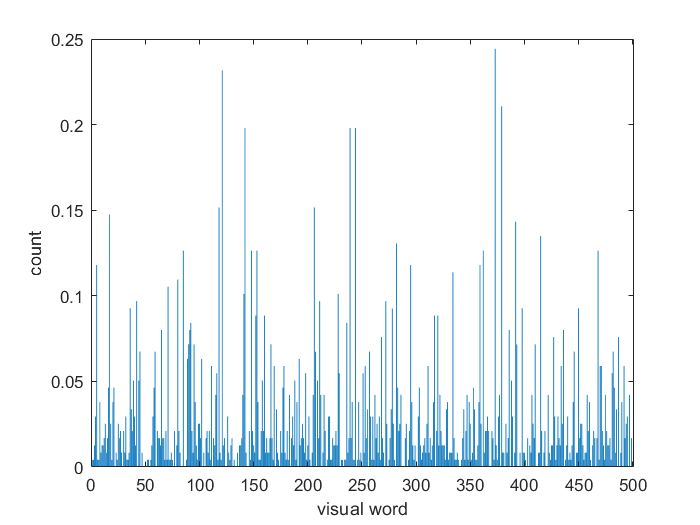

Use the vocabulary of visual words you extracted in the previous question to construct a single bag of visual words from the first image in your training `imageDatastore`. Visualise the resulting bag by plotting it as a bar graph:

(**Sanity check**: you should get something very close to the image above)

%im = training.readimage(1);
% %first image in the training stack is taken as a sample image for word bag
%im = im2gray(im);
% 
%test = words.encode(im);
% %an array of histogram scores of the first image
%bar(test)

%y = get_hogs(im)

%y = get_bag(y,words)




## Extract training data

The `Labels` property of your training `imageDatastore` contains the class labels for each of your training images, in order. Copy it into a variable called `train_labels`. Now by looping over the images in your training `imageDatastore`, and encoding each one as a bag of visual words, construct an array of corresponding bag features called `train_examples`. If you're struggling, consider checking the Matlab fundamentals for a reminder of how you can grow arrays downwards, checking the reusable code in the lecture slides, or having a play around in the Command Window to remind yourself:

(**Sanity check**: `train_examples` should be a 2D array, where each row contains all the bin totals for a single training image (so it should have the same height as `train_labels` and a width equal to the total number of visual words) call `size()` on it to check; if you get something with fewer elements consider whether you need to call `reset()` on your training `imageDatastore`)

% train_labels = training.Labels;
% train_examples=[];
% 
% while hasdata(training)
%     im = im2gray(training.read());
%     train_examples(end+1,:) = words.encode(im);
%     %creates a downward array of visual words for the classifier
% end

%size(train_examples)


## Train and evaluate an image classifier

Use the `train_examples` and `train_labels` arrays you created in the previous task to call `fitcknn()` and train a k-NN classifier with k=3 neighbours. Next, build `test_examples` and `test_labels` arrays from your testing data in just the same way you did for the previous task, and use these new arrays to evaluate your classifier's performance by computing a confusion matrix and overall classification accuracy.

(**Sanity check**: you should expect an overall classification accuracy of 83.3%)

(**Sanity check**: performance is the best we've seen yet: SURF features are powerful, offering both rotation and scale invariance, but they're also complicated to implement. In the extension tasks that follow we'll try and build a vocabulary of visual words from HOG features and repeat the classification experiments we've done here for comparison. We won't see performance at quite the same levels (HOG features aren't rotation or scale invariant) but we should still get a good improvement over our previous use of HOG features by relaxing our requirement that they always need to appear in the same place in the image, and with the potential to write all the code for ourselves.)

% test_labels = testing.Labels;
% test_examples =[];
% 
% 
% while hasdata(testing)
%     im = im2gray(testing.read());
%     test_examples(end+1,:) = words.encode(im);
% end
% 
% kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
% predictions = predict(kNN, test_examples);
% 
% [c, order] = confusionmat(test_labels, predictions);
%     
% p = sum(diag(c)) / sum(c(1:1:end)) * 100


## Preparation for extension tasks

Review your previous work and get yourself back in the position where you have built up a set of HOG features (`train_examples`) and associated class labels (`train_labels`) from the MerchData training images with repeated calls to your `get_hogs()` function (hopefully just requiring a quick copy and paste from your previous lab work). Note that you've already done the image loading and splitting up above, you just need to loop over the training data calling `get_hogs().`

You should use your `get_hogs()` function to call on the built-in `extractHOGFeatures()` function while you're working on the extension tasks below, even if you were able to implement `my_extractHOGFeatures()` function successfully. This is just because it's fast and therefore speeds things up while you're repeatedly running code and testing/debugging your work - you can always reinstate it at the end.


training.reset
trainHog =[];

while hasdata(training)
    im = im2gray(training.read());
    trainHog(end+1,:) = get_hogs(im);
end



## Extension task: finding visual words (HOG features)

Now let's try extracting a common vocabulary of HOG features. Extend the `get_words()` function stub so that it takes *all* the histograms you extracted from *all* of your training images (in the previous task), and looks for 500 clusters (or "visual words") within the resulting distribution in 9D histogram space. (Remember there are 9 bins in each histogram.) You can use Matlab's built-in `kmeans()` function to recover the clusters, but be careful to initialise it in a repeatable way (see also the lecture slides and the guidance in the function stub). We would suggest passing `get_words()` a 2D array where one row contains all the HOG features for one image -- this is what you should already have from the previous task -- and then thinking about how best to reshape it inside your `get_words()` function and before calling the `kmeans()` function. (But you are also free to do reshaping work before calling the function and pass in an array of any shape you prefer to work with.)

Add code below to call your `get_words()` function, which should return a 2D array containing the coordinates of the resulting cluster centres in the (9D) histogram space, one cluster per row:

(**Sanity check**: call `size()` on the array that results from your function call; it should have 500 rows and 9 columns)

h = trainHog;

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

sizeX = size(h,1);
sizeY = size(h,2);
total = sizeX * sizeY;

%9 being the 9D hisogram arrays
mySize = total / 9;
%above calucaltion ensures all data is rearaged to be included for the
%random sample

mydata = reshape(h,[mySize,9]);
%data is changed to hisogram 9D stardard of any length of rows

k=500;
%500 cluster centers

%random sample is taken of row legnth 500 set by K
samples = randi([1 size(mydata, 1)], k, 1);

centres = mydata(samples,:);


newCent = zeros(size(centres,1),size(centres,2));

c=0;
%for g=1:1:200

%for i=1:1:size(centres,2)
    for j=1:1:size(centres,1)

        point = centres(j,:);
        dist =  [];

        idx=randi(length(point),1);
        %selects random center start location at each cluster
        update = point(idx);
        
        
        %LOOP THIS!!!!!!!!!!!!!
        for l=1:1:size(point,1)
            for m=1:1:size(point,2)
                p = update;
                q = point(l,m);
                dist(end+1) = knn_calculate_distance(p,q);
            end
        end

       

        closest = min(dist(dist>0));
        indx = find(dist==closest);
        closest = centres(j,indx);

        new = closest+update / 2;

        centres(j,idx) = new;
        

        %LOOP THIS!!!!!!!!!!!!!
        while new<0.001
            dist = zeros(1,9);
            %dist =  [dist;1:9];



            for l=1:1:size(point,1)
                for m=1:1:size(point,2)
                    p = new;
                    q = point(l,m);
                    dist(1,m) = knn_calculate_distance(p,q);
                end
            end
            
            [B,I] = sort(dist);
            B=B(B>0);

            closest = B(1);
            indx = I(1);

            %closest = min(dist(dist>0));
            %closest = nonzeros(closest');
            

            %indx = find(dist==closest)

            % = find(dist==closest)
            
            %closest = centres(j,indx);
            
            %idx = find(centres(j,:)==new);

            %idx = centres(j,idx)
            %closest
            new = closest+new / 2;
            

            centres(j,indx) = new;
        end




        
    end
%end
%end
[~, words] = kmeans(mydata, k, 'Start', mydata(samples,:));

mydata(samples,:)
centres
words
c
%centres
%words 
%newCent

%plot(words)
%plot(centres)
%plot(new)


## Extension task: a bag of visual words for one image

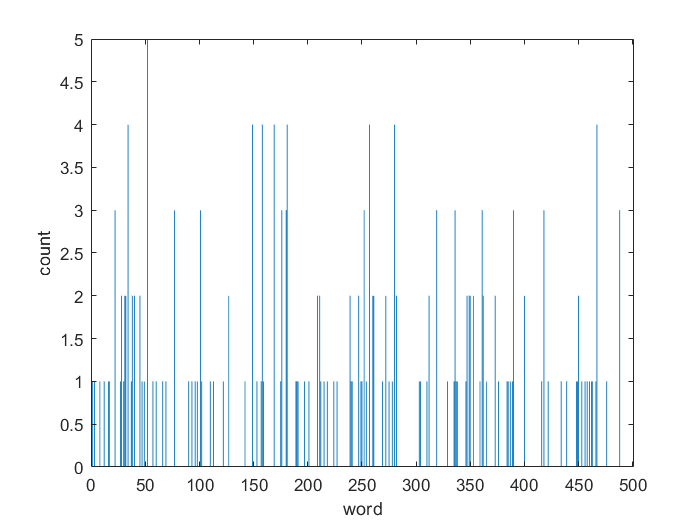

Extend the `get_bag()` function stub so that it takes an array of all the HOG features extracted from a *single* image, together with the set of visual words you extracted from your training data in the previous task, and uses them to generate a bag. Remember a bag is just a histogram that represents the image by storing, for every HOG feature you have extracted from it, which of the "visual words" (or cluster centres) lay closest in the 9D histogram space (by adding +1 to the count in its associated bin). You may wish to review the details from lectures. Again, we would suggest calling `get_bag()` with a 1D array containing all the HOG features for a single image -- as this is what `get_hogs()` returns -- and then thinking about how best to reshape it, or otherwise loop over it, inside your `get_bag()` function. (But you are also free to do reshaping work before calling the function and pass in an array of any shape you prefer to work with.) Your function should return the resulting bag as a horizontal 1D array. As the Merchandise images are all the same size, you don't need to worry about taking any steps to normalise your bags.

Add code below to extract HOG features from your first testing image (note *testing* image, and not training) with a call to `get_hogs()` and then pass the resulting array -- along with the vocabulary of visual words you calculated in the previous task -- to your `get_bag()` function in order to extract a bag. Visualise the resulting bag by plotting it as a bar graph:

(**Sanity check**: the bag for the first training image should look something like the one above (identical if you have preserved the random number seeds in this script and in `get_words()`, followed the guidance from the lecture on how to initialise the k-means algorithm, and you are calling the built-in `extractHOGFeatures()` function from your `get_hogs()` function))



% testing.reset;
% im = testing.readimage(1);
% 
% h = get_hogs(im);
% %h is perfrect
% bag = get_bag(h,words);
%bar(bag)


## Extension task: extract training data

Loop over the images in your training `imageDatastore` once again, and, by making calls to `get_hogs()` and then `get_bag()`, generate a new training array of BoVW-based features, `train_bags`. Note that you don't need to make any changes to `train_labels`, the elements of which will naturally still map to the rows your new array:

(**Sanity check**: `train_bags` should be a 2D array, where each row contains the bag for a single training image (so it should have the same height as `train_labels` and a width equal to the total number of words in the vocabulary: 500) - call `size()` on it to check)

    
% sizeX = size(h,1);
% sizeY = size(h,2);
% total = sizeX * sizeY;
% 
% %9 being the 9D hisogram arrays
% mySize = total / 9;
% 
% h = reshape(h,[mySize,9]);
% 
% new = [];
% 
% %creates empty 500 x 2 with numbered labels at 1 for binning process
% hist = 1:size(words,1);
% t = zeros(1,size(words,1));
% hist = [hist ;t];
% y = 0;
% 
% for i=1:1:size(h,1)
%     for j=1:1:size(words,1)
% 
%         q = words(j,:);
%         p = h(i,:);
% 
%         new(end+1,1) = knn_calculate_distance(p,q);
%         %call Euclidean distance calculator for each HOG feature for every
%         %word
% 
%         new(end,2) = j;
%         %adds the index for binning process
%         
% 
% 
%         if(j == size(words,1))
%             y = y+1;
%             
% 
%             cur = 0;
% 
%             new = sortrows(new,1);
%             %sorts array by smallest distance first(closest visual word)
%             new(1,2);
% 
%             cur = hist(2,new(1,2));
%             %in the empty array incase if theres
%             %already a increment
% 
%             hist(2,new(1,2)) = cur+1;
%             %adds increment at indexed word position to new histogram bin
%             %array
% 
%             new = [];
%             %clears array for next set of data
% 
%         end
%     end
% end
% 
% bag = hist(2,1:1:end);
% 
% bar(bag)
% %removes the temporay word count used for the bining process



## Extension task: train and evaluate an image classifier

Use your `train_bags` and `train_labels` arrays to call `fitcknn()` and train a k-NN classifier with k=3 neighbours. Then build a new `test_bags` array from your testing data in just the same way you did for the previous task (your `test_labels` array won't need any adjustment, as before), and use these new arrays to evaluate your classifier's performance by computing a confusion matrix and overall classification accuracy.

(**Sanity check**: you should expect a performance improvement on the HOG-based approach from the previous lab sheet: 76.7% overall classification accuracy; if you implemented your own `my_extractHOGFeatures()` function following the guidance in the previous task sheet's extension task, and you use that function for HOG extraction instead, then you should expect an overall classification accuracy of 73.3%. The difference is not significant, just down to small implementational differences discussed in the previous task sheet and the lectures)

%words = get_words(trainHog)
words = my_kmeans(trainHog,500)

train_labels = training.Labels;
train_bags = [];

training.reset;

while hasdata(training)
    im = training.read();
    h = get_hogs(im);
    train_bags(end+1,:) = get_bag(h,words);
end

test_labels = testing.Labels;
test_bags =[];

testing.reset;

while hasdata(testing)
    im = testing.read();
    h = get_hogs(im);
    test_bags(end+1,:) = get_bag(h,words);
end

kNN = fitcknn(train_bags, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, test_bags);

[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100


 



     



## Extension task: implementing k-means

Try implementing the k-means algorithm for yourself by writing a `my_kmeans()` function and checking that you can get identical results to the built-in `kmeans()` function. There's no function stub to extend, it's over to you for this one. You should include the usual documentation at the top.

Substitute the call to `kmeans()` in your `get_words()` function for a call to your new `my_kmeans()` function and check that your answers to the earlier tasks still give the exact same results (classification accuracies, plus bar graph of the first image's bag). Switch back and forth between calling `kmeans()` and `my_kmeans()` a few times, re-running this live script each time, to convince yourself it is working as it should.

(**Sanity check**: notice that guidance for calling `kmeans()` given in lectures has been carefully written so that you can see the exact indices of the data which are used to initialise the clusters' starting locations (see the call to `randi()` which generates those indices); you can therefore use the exact same initialisation in order to check you get the exact same result)

(**Well done**: well done if you got to this stage. We've got our overall classification rate about as high as we can; and you've been able to implement all the steps for yourself. We'll need to move on to more advanced feature extraction techniques and more advanced classifiers in order to do better. All the way up to 100% accuracy is possible on the MerchData... More next week. Move on and try any extension tasks you have left incomplete in the meantime (there is also an optional one below))

## Extension task (optional): porting Matlab work to other languages

[**Note: this task isn't required for 1CWK50 but it is submissible and you may enjoy working on it as it gives a chance to practice/demonstrate skills in other languages; feel free to skip it if you want to**]

In the Matlab Fundamentals, and in the lectures, we have talked about Matlab as a prototyping language. The idea is that we can prototype an approach to a problem quite quickly, checking that results are acceptable, and then once confident port our approach into another language, checking back against the Matlab implementation to verify technical correctness.

So far on this unit you have implemented techniques for yourself in standalone .m file functions (e.g., `my_im2gray()`, `my_imgradientxy()`, `my_imgradient()`, `my_extractHOGFeatures()`, `get_words()`, `get_bag()`, ...). All of this work can potentially be submitted for credit as part of your 1CWK50 submission. However, if you would *like to* (there is no requirement, it's just an option) the 1CWK50 specfication also allows you to submit your own implementations written in other languages, *providing they are called from a Matlab live script*. 

Guidance on calling code written in other languages from your live scripts is available [here](https://uk.mathworks.com/products/matlab/matlab-and-other-programming-languages.html)

This gives people who have found the extension exercises reasonably easy and/or completed them reasonably quickly a chance to port their work to other languages they enjoy working with (e.g, Java) or languages they want to learn more about. It's a good chance to practice, maintain and develop skills in other areas and also to add some nice ML work to your overall portfolio of coding work.

And beyond the scope of 1CWK50 you're of course free to try implementing anything that takes your fancy, prototyping with Matlab first and then comparing back to validate your work in other languages. E.g., remember that it's possible to implement both Naive Bayes and Decision Tree classifiers and get exact agreement with the built-in Matlab functions (`fitcnb()` and `fitctree()`). Or there may be other ML topics that interest you. Or you may like to try something more low-level, like building an equivalent of the `imageDatastore` class. Whatever takes your fancy, Matlab should always be your starting point for testing things out and deciding exactly what you will attempt in other languages, and also your ending point, giving you guaranteed correct results that you can compare back against to verify technical correctness.